## Import the data

#### Import CSV file

clearvars;
% filename = 'Data/20230322_1/400V_1.0MSs_5ohm_17_20230322103933251.5V_5ohm_-3V_ALL.csv';
% filename = 'Data/20230322_1/400V_1.0MSs_5ohm_17_20230322104327251.5V_5ohm_-3V_ALL.csv';
filename = 'Data/FFT_Test/Pulse_60_Vds_350_Vgson_175_Vgsoff_30_ALL_20230425140645918.csv'

filename = 'Data/FFT_Test/Pulse_60_Vds_350_Vgson_175_Vgsoff_30_ALL_20230425140645918.csv'

data = readtable(filename);

#### Data parsing

data = renamevars(data, "Labels", "Time");
t = data.Time;
Vgs = data.Vgs;
Vds = data.Vds;
Id = data.Id; 

## Plot the imported data

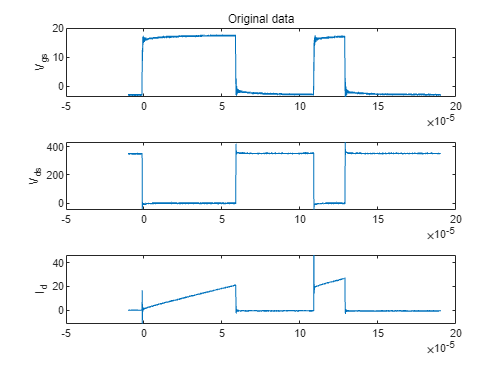

figure;

subplot(3,1,1);
plot(t, Vgs);
ylabel("V_{gs}");
title("Original data");

subplot(3,1,2);
plot(t, Vds);
ylabel("V_{ds}");

subplot(3,1,3);
plot(t, Id);
ylabel("I_d");

## Find the switching transient

#### Eliminate the mean value in Vds

to find the switching transient by means of finding the zerocrossing of Vds waveform.

Vds_mean = mean(Vds)

Vds_mean = 210.5149

Vds_zeromean = Vds - Vds_mean;

#### Find the zerocrossing

min_gap = 10000; % Arbitrary value

zero_crossings = Find_zeroCrossing(Vds_zeromean, min_gap);
assert(length(zero_crossings) == 4, "Error: Switching transient detection failed")

% Interpolate the time values corresponding to the zero crossings
zero_crossing_times = interp1(1:length(t), t, zero_crossings);
clear zero_crossings

#### Parse the zerocrossing point to switching transient

zero_crossing_names = {"Charging"; "Turn-Off"; "Turn-On"; "End"}

zero_crossing_names = 4×1 cell 배열
    {["Charging"]}
    {["Turn-Off"]}
    {["Turn-On" ]}
    {["End"     ]}


st_time = containers.Map();
for i = 1:4
    st_time(zero_crossing_names{i}) = zero_crossing_times(i);
end
clear i
disp(keys(st_time))

    {'Charging'}    {'End'}    {'Turn-Off'}    {'Turn-On'}



disp(values(st_time))

    {[-1.1154e-06]}    {[1.2894e-04]}    {[5.8951e-05]}    {[1.0889e-04]}



#### Plot the zerocrossing 

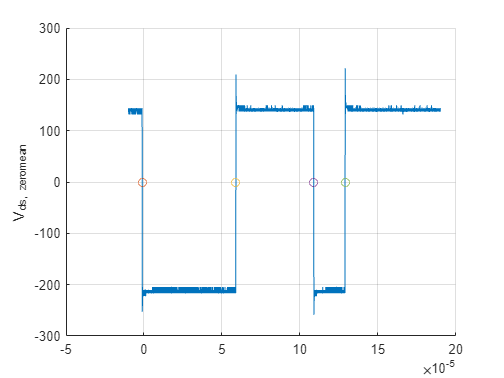

figure;
hold on;
plot(t, Vds_zeromean);
scatter(zero_crossing_times, 0);
ylabel("V_{ds, zeromean}");
grid on;
hold off;

clear zero_crossing_times zero_crossing_names
clear Vds_mean Vds_zeromean
clear min_gap

#### Find the switching transients

% st_time_range = 0.1 * [-1e-6 9e-6];
% st_time_range = 0.1 * [-0.3e-6 9.7e-6];
st_time_range = 0.1 * [1e-6 11e-6];

Turn-Off transient

turnoff_time_range = st_time("Turn-Off") + st_time_range;
index_turnoff = (turnoff_time_range(1) < t) & (t < turnoff_time_range(2));
t_turnoff = t(index_turnoff);
Vgs_turnoff = Vgs(index_turnoff);
Vds_turnoff = Vds(index_turnoff);
Id_turnoff = Id(index_turnoff);

Turn-On transient 

turnon_time_range = st_time("Turn-On") + st_time_range;
index_turnon = (turnon_time_range(1) < t) & (t < turnon_time_range(2));
t_turnon = t(index_turnon);
Vgs_turnon = Vgs(index_turnon);
Vds_turnon = Vds(index_turnon);
Id_turnon = Id(index_turnon);

clear turnoff_time_range turnon_time_range
clear index_turnoff index_turnon
clear st_time_range

Data to table

data_turnoff = table();
data_turnoff.t = t_turnoff;
data_turnoff.Vgs = Vgs_turnoff;
data_turnoff.Vds = Vds_turnoff;
data_turnoff.Id = Id_turnoff;

data_turnon = table();
data_turnon.t = t_turnon;
data_turnon.Vgs = Vgs_turnon;
data_turnon.Vds = Vds_turnon;
data_turnon.Id = Id_turnon;

data_trs = table();
data_trs.turnoff = data_turnoff;
data_trs.turnon = data_turnon;

data_raw = table();
data_raw.t = t;
data_raw.Vgs = Vgs;
data_raw.Vds = Vds;
data_raw.Id = Id;

clear t_turnoff Vgs_turnoff Vds_turnoff Id_turnoff t_turnon Vgs_turnon Vds_turnon Id_turnon
clear t Vgs Vds Id
clear data_turnoff data_turnon

Plot at the transient

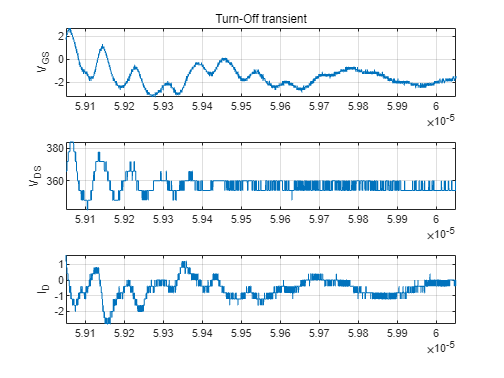

turnoff_time_range = [data_trs.turnoff.t(1) data_trs.turnoff.t(end)];
t_turnoff = data_trs.turnoff.t;
Vgs_turnoff = data_trs.turnoff.Vgs;
Vds_turnoff = data_trs.turnoff.Vds;
Id_turnoff = data_trs.turnoff.Id;

figure;
subplot(3,1,1)
plot(t_turnoff, Vgs_turnoff);
ylabel("V_{GS}");
xlim(turnoff_time_range);
title("Turn-Off transient")
grid on;
subplot(3,1,2)
plot(t_turnoff, Vds_turnoff);
ylabel("V_{DS}");
xlim(turnoff_time_range)
grid on;
subplot(3,1,3)
plot(t_turnoff, Id_turnoff);
ylabel("I_{D}");
xlim(turnoff_time_range)
grid on;

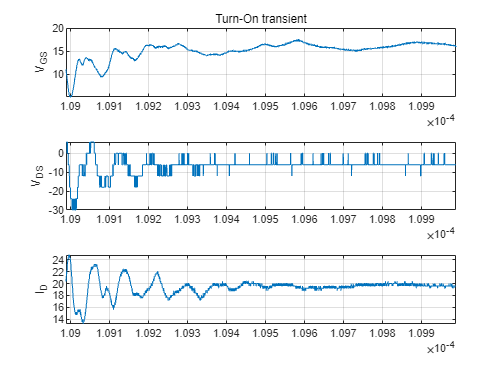

turnon_time_range = [data_trs.turnon.t(1) data_trs.turnon.t(end)];
t_turnon = data_trs.turnon.t;
Vgs_turnon = data_trs.turnon.Vgs;
Vds_turnon = data_trs.turnon.Vds;
Id_turnon = data_trs.turnon.Id;

figure;
subplot(3,1,1)
plot(t_turnon, Vgs_turnon);
ylabel("V_{GS}");
xlim(turnon_time_range)
title("Turn-On transient")
grid on;
subplot(3,1,2)
plot(t_turnon, Vds_turnon);
ylabel("V_{DS}");
xlim(turnon_time_range)
grid on;
subplot(3,1,3)
plot(t_turnon, Id_turnon);
ylabel("I_{D}");
xlim(turnon_time_range)
grid on;

clear turnoff_time_range turnon_time_range
clear t_turnoff Vgs_turnoff Vds_turnoff Id_turnoff
clear t_turnon Vgs_turnon Vds_turnon Id_turnon

## Perform FFT

Parse internal variables

t = data_raw.t;
Vgs_turnoff = data_trs.turnoff.Vgs;
Vds_turnoff = data_trs.turnoff.Vds;
Id_turnoff = data_trs.turnoff.Id;
Vgs_turnon = data_trs.turnon.Vgs;
Vds_turnon = data_trs.turnon.Vds;
Id_turnon = data_trs.turnon.Id;

Sampling frequency

fs = length(t)/(t(length(t)) - t(1))

fs = 6.2500e+09

For Turn-off transient

N_fft = length(Vgs_turnoff);
fft_Id_turnoff = fft(Id_turnoff, N_fft);
fft_Vds_turnoff = fft(Vds_turnoff, N_fft);
fft_Vgs_turnoff = fft(Vgs_turnoff, N_fft);

For Turn-on transient

N_fft = length(Vgs_turnon);
fft_Id_turnon = fft(Id_turnon, N_fft);
fft_Vds_turnon = fft(Vds_turnon, N_fft);
fft_Vgs_turnon = fft(Vgs_turnon, N_fft);

`Calculate the corresponding frequency vector`

N_turnoff = N_fft;
f_turnoff = ((0:(N_turnoff-1))*(fs/N_turnoff))';
N_turnon = N_fft;
f_turnon = ((0:(N_turnon-1))*(fs/N_turnon))';

clear t
clear Vgs_turnoff Vds_turnoff Id_turnoff
clear Vgs_turnon Vds_turnon Id_turnon
clear N_turnoff N_turnon N_fft fs

Data to table

fft_turnoff = table();
fft_turnoff.f = f_turnoff;
fft_turnoff.Vgs = fft_Vgs_turnoff;
fft_turnoff.Vds = fft_Vds_turnoff;
fft_turnoff.Id = fft_Id_turnoff;

fft_turnon = table();
fft_turnon.f = f_turnon;
fft_turnon.Vgs = fft_Vgs_turnon;
fft_turnon.Vds = fft_Vds_turnon;
fft_turnon.Id = fft_Id_turnon;

fft_trs = table();
fft_trs.turnoff = fft_turnoff;
fft_trs.turnon = fft_turnon;

clear f_turnoff fft_Vgs_turnoff fft_Vds_turnoff fft_Id_turnoff
clear f_turnon fft_Vgs_turnon fft_Vds_turnon fft_Id_turnon
clear fft_turnoff fft_turnon

#### Plot the FFT result

Turn Off

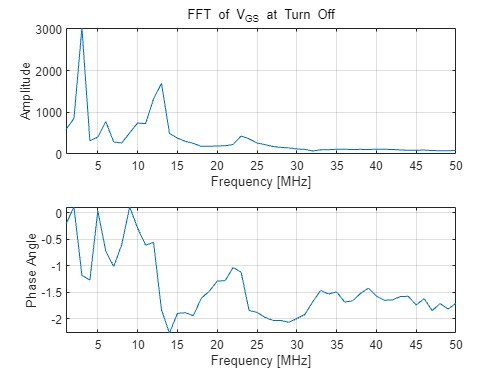

f_lim = [1e6 50e6];

f_turnoff = fft_trs.turnoff.f;
fft_Vgs_turnoff = fft_trs.turnoff.Vgs;
fft_Vds_turnoff = fft_trs.turnoff.Vds;
fft_Id_turnoff = fft_trs.turnoff.Id;

figure;
subplot(2,1,1);
plot(f_turnoff/1e6, abs(fft_Vgs_turnoff));
title("FFT of V_{GS} at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnoff/1e6, angle(fft_Vgs_turnoff));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
grid on;
xlim(f_lim/1e6);

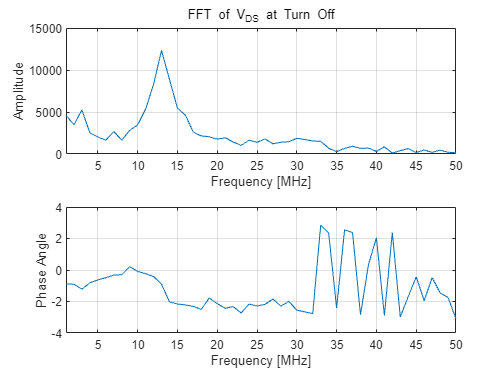

figure;
subplot(2,1,1);
plot(f_turnoff/1e6, abs(fft_Vds_turnoff));
title("FFT of V_{DS} at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnoff/1e6, angle(fft_Vds_turnoff));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
grid on;
xlim(f_lim/1e6);

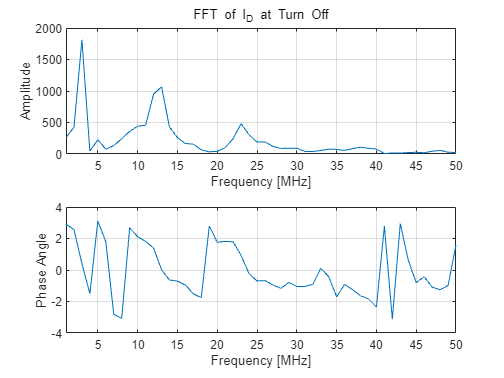


figure;
subplot(2,1,1);
plot(f_turnoff/1e6, abs(fft_Id_turnoff));
title("FFT of I_D at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnoff/1e6, angle(fft_Id_turnoff));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
grid on;
xlim(f_lim/1e6);

clear f_turnoff fft_Vgs_turnoff fft_Vds_turnoff fft_Id_turnoff
clear f_lim

Turn On

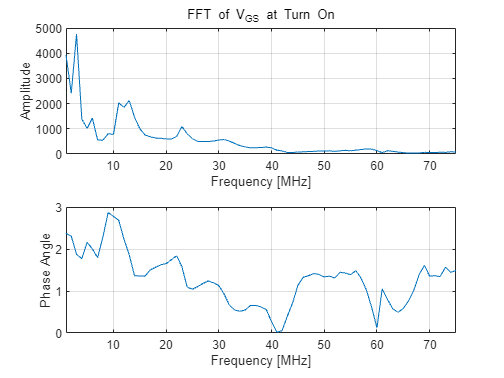

f_lim = [1e6 75e6];

f_turnon = fft_trs.turnon.f;
fft_Vgs_turnon = fft_trs.turnon.Vgs;
fft_Vds_turnon = fft_trs.turnon.Vds;
fft_Id_turnon = fft_trs.turnon.Id;

figure;
subplot(2,1,1);
plot(f_turnon/1e6, abs(fft_Vgs_turnon));
title("FFT of V_{GS} at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnon/1e6, angle(fft_Vgs_turnon));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
grid on;
xlim(f_lim/1e6);

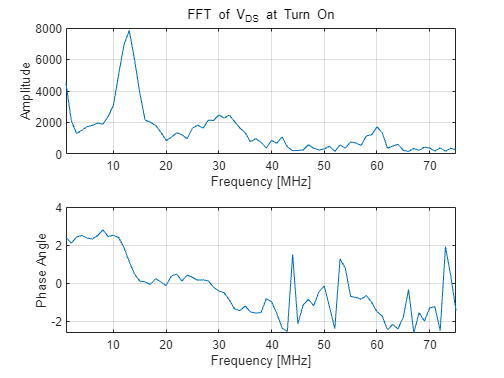

figure;
subplot(2,1,1);
plot(f_turnon/1e6, abs(fft_Vds_turnon));
title("FFT of V_{DS} at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnon/1e6, angle(fft_Vds_turnon));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
grid on;
xlim(f_lim/1e6);

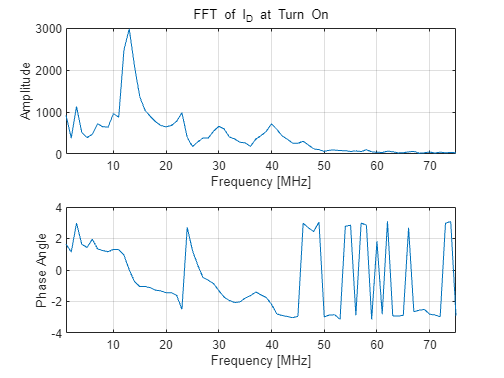


figure;
subplot(2,1,1);
plot(f_turnon/1e6, abs(fft_Id_turnon));
title("FFT of I_D at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnon/1e6, angle(fft_Id_turnon));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
grid on;
xlim(f_lim/1e6);

clear f_turnon fft_Vgs_turnon fft_Vds_turnon fft_Id_turnon
clear f_lim

#### Zeromean FFT

Eliminate mean from the data

data_turnoff_arr_with_t = table2array(data_trs.turnoff);
data_turnoff_arr = data_turnoff_arr_with_t(:, 2:end);
clear data_turnoff_arr_with_t
data_turnoff_mean = mean(data_turnoff_arr);
data_turnoff_zm = data_turnoff_arr - data_turnoff_mean

data_turnoff_zm =     3.3903    8.4307    2.1531
    3.1903    8.4307    2.1531
    3.1903    8.4307    1.7531
    3.3903    8.4307    1.7531
    3.3903    8.4307    1.7531
    3.3903    8.4307    1.7531
    3.3903    8.4307    1.7531
    3.3903    8.4307    1.7531
    3.5903    8.4307    1.3531
    3.5903    8.4307    1.3531



data_trs_turnoff_zm = data_trs.turnoff;
data_trs_turnoff_zm{:, 2:4} = data_turnoff_zm;

data_trs_zm = table();
data_trs_zm.turnoff = data_trs_turnoff_zm;

data_turnon_arr_with_t = table2array(data_trs.turnon);
data_turnon_arr = data_turnon_arr_with_t(:, 2:end);
clear data_turnon_arr_with_t
data_turnon_mean = mean(data_turnon_arr);
data_turnon_zm = data_turnon_arr - data_turnon_mean;

data_trs_turnon_zm = data_trs.turnon;
data_trs_turnon_zm{:, 2:4} = data_turnon_zm;

data_trs_zm.turnon = data_trs_turnon_zm

data_trs_zm = 6250×2 table
                    turnoff                                       turnon                  
        t          Vgs       Vds        Id          t           Vgs       Vds        Id   
    ________________________________________    __________________________________________

    5.9051e-05    3.3903    8.4307    2.1531    0.00010899    -4.0444    12.646     1.3864
    5.9051e-05    3.1903    8.4307    2.1531    0.00010899    -4.2444    12.646    0.98637
    5.9051e-05    3.1903    8.4307    1.7531    0.00010899    -4.4444    12.646    0.98637
    5.9051e-05    3.3903    8.4307    1.7531    0.00010899    -4.4444    12.646     1.3864
    5.9051e-05    3.3903    8.4307    1.7531    0.00010899    -4.6444    12.646     1.3864
    5.9052e-05    3.3903    8.4307    1.7531    0.00010899    -4.6444    12.646     1.7864
    5.9052e-05    3.3903    8.4307    1.7531    0.00010899    -4.8444    12.646     1.7864
    5.9052e-05    3.3903    8.4307    1.7531    0.00010899    

clear data_turnoff_arr data_turnoff_mean data_turnoff_zm data_trs_turnoff_zm
clear data_turnon_arr data_turnon_mean data_turnon_zm data_trs_turnon_zm

Parse internal variables

t = data_raw.t;
Vgs_turnoff = data_trs_zm.turnoff.Vgs;
Vds_turnoff = data_trs_zm.turnoff.Vds;
Id_turnoff = data_trs_zm.turnoff.Id;
Vgs_turnon = data_trs_zm.turnon.Vgs;
Vds_turnon = data_trs_zm.turnon.Vds;
Id_turnon = data_trs_zm.turnon.Id;

Sampling frequency

fs = length(t)/(t(length(t)) - t(1))

fs = 6.2500e+09

For Turn-off transient

N_fft = length(Vgs_turnoff);
fft_Id_turnoff_zm = fft(Id_turnoff, N_fft);
fft_Vds_turnoff_zm = fft(Vds_turnoff, N_fft);
fft_Vgs_turnoff_zm = fft(Vgs_turnoff, N_fft);

For Turn-on transient

N_fft = length(Vgs_turnon);
fft_Id_turnon_zm = fft(Id_turnon, N_fft);
fft_Vds_turnon_zm = fft(Vds_turnon, N_fft);
fft_Vgs_turnon_zm = fft(Vgs_turnon, N_fft);

`Calculate the corresponding frequency vector`

N_turnoff = N_fft;
f_turnoff_zm = ((0:(N_turnoff-1))*(fs/N_turnoff))';
N_turnon = N_fft;
f_turnon_zm = ((0:(N_turnon-1))*(fs/N_turnon))';

clear t
clear Vgs_turnoff Vds_turnoff Id_turnoff
clear Vgs_turnon Vds_turnon Id_turnon
clear N_turnoff N_turnon N_fft fs

Data to table

fft_turnoff_zm = table();
fft_turnoff_zm.f = f_turnoff_zm;
fft_turnoff_zm.Vgs = fft_Vgs_turnoff_zm;
fft_turnoff_zm.Vds = fft_Vds_turnoff_zm;
fft_turnoff_zm.Id = fft_Id_turnoff_zm;

fft_turnon_zm = table();
fft_turnon_zm.f = f_turnon_zm;
fft_turnon_zm.Vgs = fft_Vgs_turnon_zm;
fft_turnon_zm.Vds = fft_Vds_turnon_zm;
fft_turnon_zm.Id = fft_Id_turnon_zm;

fft_trs_zm = table();
fft_trs_zm.turnoff = fft_turnoff_zm;
fft_trs_zm.turnon = fft_turnon_zm;

clear f_turnoff_zm fft_Vgs_turnoff_zm fft_Vds_turnoff_zm fft_Id_turnoff_zm
clear f_turnon_zm fft_Vgs_turnon_zm fft_Vds_turnon_zm fft_Id_turnon_zm
clear fft_turnoff_zm fft_turnon_zm

#### Plot the FFT result

Turn Off

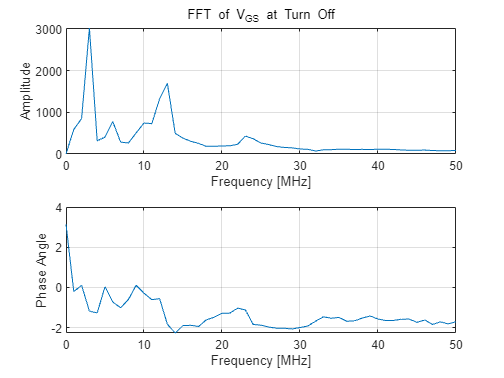

f_lim = [0e6 50e6];

f_turnoff = fft_trs_zm.turnoff.f;
fft_Vgs_turnoff = fft_trs_zm.turnoff.Vgs;
fft_Vds_turnoff = fft_trs_zm.turnoff.Vds;
fft_Id_turnoff = fft_trs_zm.turnoff.Id;

figure;
subplot(2,1,1);
plot(f_turnoff/1e6, abs(fft_Vgs_turnoff));
title("FFT of V_{GS} at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnoff/1e6, angle(fft_Vgs_turnoff));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
grid on;
xlim(f_lim/1e6);

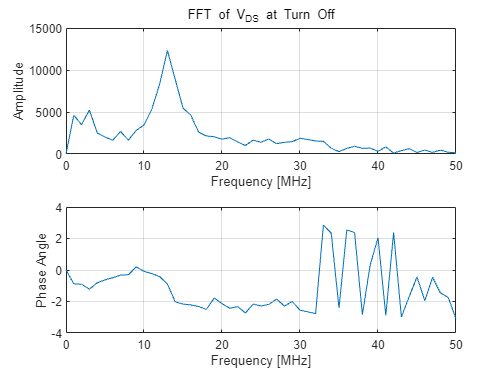

figure;
subplot(2,1,1);
plot(f_turnoff/1e6, abs(fft_Vds_turnoff));
title("FFT of V_{DS} at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnoff/1e6, angle(fft_Vds_turnoff));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
grid on;
xlim(f_lim/1e6);

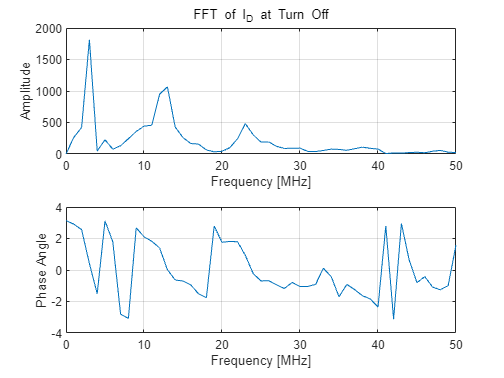


figure;
subplot(2,1,1);
plot(f_turnoff/1e6, abs(fft_Id_turnoff));
title("FFT of I_D at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnoff/1e6, angle(fft_Id_turnoff));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
grid on;
xlim(f_lim/1e6);

clear f_turnoff fft_Vgs_turnoff fft_Vds_turnoff fft_Id_turnoff
clear f_lim

Turn On

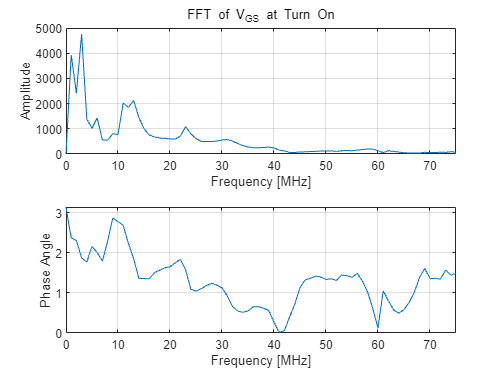

f_lim = [0e6 75e6];

f_turnon = fft_trs_zm.turnon.f;
fft_Vgs_turnon = fft_trs_zm.turnon.Vgs;
fft_Vds_turnon = fft_trs_zm.turnon.Vds;
fft_Id_turnon = fft_trs_zm.turnon.Id;

figure;
subplot(2,1,1);
plot(f_turnon/1e6, abs(fft_Vgs_turnon));
title("FFT of V_{GS} at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnon/1e6, angle(fft_Vgs_turnon));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
grid on;
xlim(f_lim/1e6);

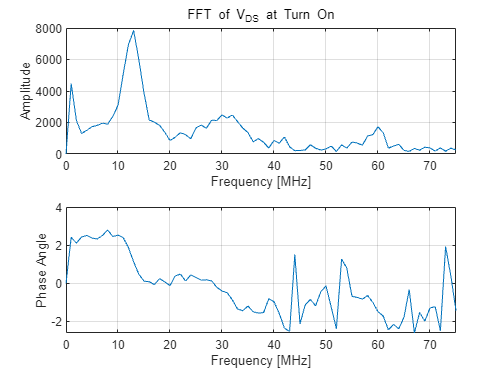

figure;
subplot(2,1,1);
plot(f_turnon/1e6, abs(fft_Vds_turnon));
title("FFT of V_{DS} at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnon/1e6, angle(fft_Vds_turnon));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
grid on;
xlim(f_lim/1e6);

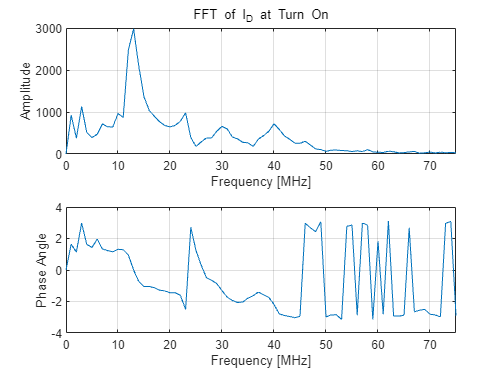


figure;
subplot(2,1,1);
plot(f_turnon/1e6, abs(fft_Id_turnon));
title("FFT of I_D at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnon/1e6, angle(fft_Id_turnon));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
grid on;
xlim(f_lim/1e6);

clear f_turnon fft_Vgs_turnon fft_Vds_turnon fft_Id_turnon
clear f_lim

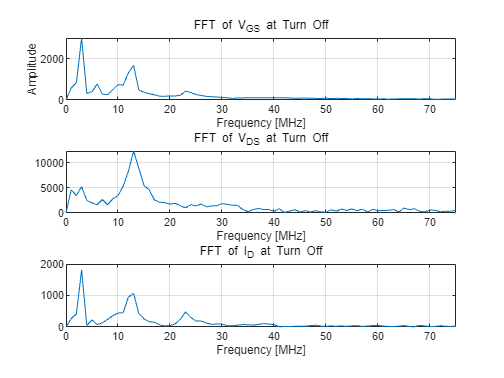

f_lim = [0e6 75e6];

f_turnoff = fft_trs_zm.turnoff.f;
fft_Vgs_turnoff = fft_trs_zm.turnoff.Vgs;
fft_Vds_turnoff = fft_trs_zm.turnoff.Vds;
fft_Id_turnoff = fft_trs_zm.turnoff.Id;

figure;
subplot(3,1,1);
plot(f_turnoff/1e6, abs(fft_Vgs_turnoff));
title("FFT of V_{GS} at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(3,1,2);
plot(f_turnoff/1e6,  abs(fft_Vds_turnoff));
title("FFT of V_{DS} at Turn Off");
xlabel("Frequency [MHz]");
grid on;
xlim(f_lim/1e6);

subplot(3,1,3);
plot(f_turnoff/1e6,  abs(fft_Id_turnoff));
title("FFT of I_{D} at Turn Off");
xlabel("Frequency [MHz]");
grid on;
xlim(f_lim/1e6);

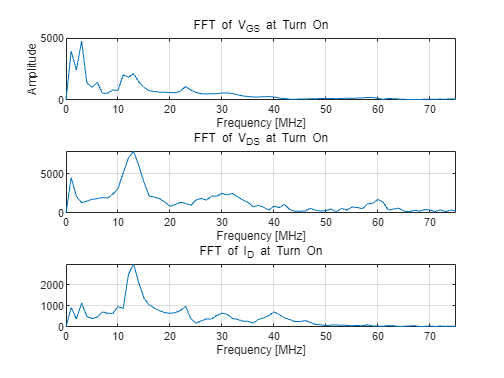

f_lim = [0e6 75e6];

f_turnon = fft_trs_zm.turnon.f;
fft_Vgs_turnon = fft_trs_zm.turnon.Vgs;
fft_Vds_turnon = fft_trs_zm.turnon.Vds;
fft_Id_turnon = fft_trs_zm.turnon.Id;

figure;
subplot(3,1,1);
plot(f_turnon/1e6, abs(fft_Vgs_turnon));
title("FFT of V_{GS} at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
grid on;
xlim(f_lim/1e6);

subplot(3,1,2);
plot(f_turnon/1e6,  abs(fft_Vds_turnon));
title("FFT of V_{DS} at Turn On");
xlabel("Frequency [MHz]");
grid on;
xlim(f_lim/1e6);

subplot(3,1,3);
plot(f_turnon/1e6,  abs(fft_Id_turnon));
title("FFT of I_{D} at Turn On");
xlabel("Frequency [MHz]");
grid on;
xlim(f_lim/1e6);

clear f_lim f_turnoff f_turnon
clear fft_Id_turnoff fft_Vgs_turnoff fft_Vds_turnoff
clear fft_Id_turnon fft_Vgs_turnon fft_Vds_turnon